data1og = randn(100,1); 
mean(data1og);
data2og = randn(100,1);
mean(data2og);
data3og=[data1og;data2og]

data3og =     0.6307
    0.3404
   -0.2718
   -2.1067
    0.0365
   -1.2498
   -0.6184
    0.8312
   -0.8500
    0.8431


% Mission 1 generate two normally distributed datasets of N(1,0) and N(0.5,1)
fprintf('hello world');

hello world

sigma=0.8

sigma = 0.8000




fprintf("the sigma now is %.4f", sigma);

the sigma now is 0.8000


data1 = sigma*data1og; 
mean(data1);
data2 = sigma*data2og+0.5 ;

mean(data2);
data3=[data1;data2];

k1=[];
k2=[];
g1=[];
g2=[];

result=[];
k1=[];
k2=[];
for i=1:50
    n_clusters=2;
    % Fit a GMM model with 2 components
    options = statset('MaxIter', 5000, 'TolFun', 1e-10);
    %options = statset('MaxIter', 3000, 'TolFun', 1e-8);
    %gmm = fitgmdist(data3, n_clusters, 'CovarianceType','diagonal','Options', options);
    gmm = fitgmdist(data3, n_clusters,'Options', options);
    
    % Get the predicted labels for each data point
    labels = cluster(gmm, data3);
    
    % Get the centroids for each Gaussian component
    centroids_GMM = gmm.mu;
    % Perform KMeans clustering with 3 clusters
    [idx, centroids_Kmeans] = kmeans(data3, 2);
    k1(end+1)=centroids_GMM(1);
    k2(end+1)=centroids_GMM(2);
    g1(end+1)=centroids_Kmeans(1);
    g2(end+1)=centroids_Kmeans(2);
end

result=[k1' k2']

result =     0.4638   -0.8432
   -0.8432    0.4638
   -0.8432    0.4638
   -0.8432    0.4638
    0.4638   -0.8432
    0.2098    0.8920
   -0.8432    0.4638
    0.4638   -0.8432
   -0.8432    0.4638
   -0.8432    0.4638


num_clusters = 2;
kmeans_SI = zeros(size(num_clusters));
kmeans_DBI = zeros(size(num_clusters));
gmm_SI = zeros(size(num_clusters));
gmm_DBI = zeros(size(num_clusters));

data = [randn(100, 2); 5 + randn(100, 2)];

for i = 1:length(num_clusters)
    k = num_clusters(i);
    
    % k-means clustering
    kmeans_clusters = kmeans(data3, k);
    kmeans_SI(i) = mean(silhouette(data3, kmeans_clusters));
    kmeans_DBI_obj = evalclusters(data3, kmeans_clusters, 'DaviesBouldin');
    kmeans_DBI(i) = kmeans_DBI_obj.CriterionValues;
    
    % GMM clustering
    options = statset('MaxIter', 5000, 'TolFun', 1e-10);
    gmm_model = fitgmdist(data3, k, 'Options', options);
    gmm_clusters = cluster(gmm_model, data3);
    
    gmm_DBI_obj = evalclusters(data3, gmm_clusters, 'DaviesBouldin');
    gmm_DBI(i) = gmm_DBI_obj.CriterionValues;

end

% % Compute k-means and GMM clusters for different numbers of clusters
% X=data3;
% num_clusters = 2:6;
% kmeans_SI = zeros(size(num_clusters));
% gmm_SI = zeros(size(num_clusters));
% for k = num_clusters
%     % Compute k-means clusters and SI
%     kmeans_clusters = kmeans(X, k);
%     kmeans_SI(k-1) = mean(silhouette(X, kmeans_clusters));
%     
%     % Compute GMM clusters and SI
%     gmm_model = fitgmdist(X, k, 'RegularizationValue', 1e-6);
%     gmm_clusters = cluster(gmm_model, X);
%     gmm_SI(k-1) = mean(silhouette(X, gmm_clusters));
% end
% 
% % Display SI scores for k-means and GMM
% fprintf('Silhouette Index for k-means: %.4f %.4f %.4f %.4f %.4f\n', kmeans_SI);
% fprintf('Silhouette Index for GMM: %.4f %.4f %.4f %.4f %.4f\n', gmm_SI);
% 
% % Plot SI scores for k-means and GMM
% figure;
% plot(num_clusters, kmeans_SI, 'o-', 'LineWidth', 2, 'MarkerSize', 10);
% hold on;
% plot(num_clusters, gmm_SI, 'o-', 'LineWidth', 2, 'MarkerSize', 10);
% xlabel('Number of clusters');
% ylabel('Silhouette Index');
% title('Comparison of k-means and GMM clustering using Silhouette Index');
% legend('K-means', 'GMM');
% grid on;

**绘图**

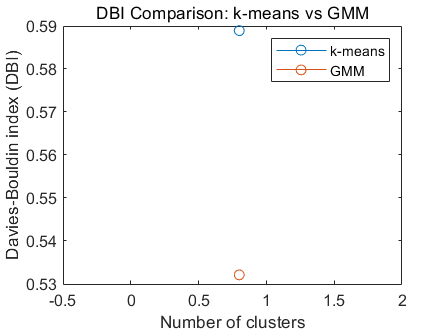

% Plot DBI comparison
figure;
plot(sigma, kmeans_DBI, '-o', 'DisplayName', 'k-means');
hold on;
plot(sigma, gmm_DBI, '-o', 'DisplayName', 'GMM');
xlabel('Number of clusters');
ylabel('Davies-Bouldin index (DBI)');
title('DBI Comparison: k-means vs GMM');
legend;
hold off;

k1=[];
k2=[];
g1=[];
g2=[];

num_clusters = 2;
kmeans_DBI = [];
gmm_DBI = [];
kmeans_si=[];
gmm_si=[];

sigmalist=0.1:0.1:1;
for i=1:length(sigmalist)
    sigma=sigmalist(i)
    data1 = sigma*data1og; 
    mean(data1);
    data2 = sigma*data2og+0.5 ;
    
    mean(data2);
    data4=[data1;data2];   
    k = 2;
    % k-means clustering
    kmeans_clusters = kmeans(data4, k);    
    kmeans_DBI_obj = evalclusters(data4, kmeans_clusters, 'DaviesBouldin');
    kmeans_DBI(end+1) = kmeans_DBI_obj.CriterionValues;

    kmeans_silhouette_values = mean(silhouette(data4, kmeans_clusters))
    kmeans_si(end+1)=kmeans_silhouette_values;
    
    % GMM clustering
    options = statset('MaxIter', 5000, 'TolFun', 1e-10);
    gmm_model = fitgmdist(data4, k, 'Options', options);
    gmm_model.AIC
    gmm_clusters = cluster(gmm_model, data4);    
    gmm_DBI_obj = evalclusters(data4, gmm_clusters, 'DaviesBouldin');
    gmm_DBI(end+1) = gmm_DBI_obj.CriterionValues;
    gmm_silhouette_values = mean(silhouette(data4, gmm_clusters))

    gmm_si(end+1)=gmm_silhouette_values;
    
    
    
    
end

sigma = 0.1000

kmeans_silhouette_values = 0.8898

ans = -45.7184

gmm_silhouette_values = 0.8898

sigma = 0.2000

kmeans_silhouette_values = 0.7876

ans = 125.4039

gmm_silhouette_values = 0.7697

sigma = 0.3000

kmeans_silhouette_values = 0.7298

ans = 223.8195

gmm_silhouette_values = 0.7236

sigma = 0.4000

kmeans_silhouette_values = 0.7248

ans = 305.6556

gmm_silhouette_values = 0.6051

sigma = 0.5000

kmeans_silhouette_values = 0.7166

ans = 376.6899

gmm_silhouette_values = 0.5677

sigma = 0.6000

kmeans_silhouette_values = 0.7117

ans = 438.8210

gmm_silhouette_values = 0.5443

sigma = 0.7000

kmeans_silhouette_values = 0.7072

ans = 493.6081

gmm_silhouette_values = 0.5326

sigma = 0.8000

kmeans_silhouette_values = 0.7046

ans = 542.3878

gmm_silhouette_values = 0.5279

sigma = 0.9000

kmeans_silhouette_values = 0.7059

ans = 586.2323

gmm_silhouette_values = 0.5255

sigma = 1

kmeans_silhouette_values = 0.7062

ans = 625.9838

gmm_silhouette_values = 0.5281

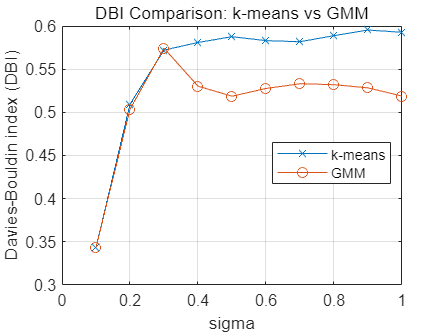

figure;
plot(sigmalist, kmeans_DBI, '-x', 'DisplayName', 'k-means');
hold on;
plot(sigmalist, gmm_DBI, '-o', 'DisplayName', 'GMM');
xlabel('sigma');
ylabel('Davies-Bouldin index (DBI)');
title('DBI Comparison: k-means vs GMM');
legend;
hold off;

grid on
legend("Position",[0.61885,0.66898,0.26745,0.12236])

legend(["k-means","GMM"])
legend("Position",[0.61209,0.44943,0.26745,0.12236])

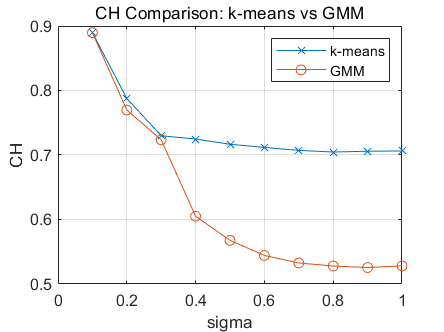


figure;
plot(sigmalist, kmeans_si, '-x', 'DisplayName', 'k-means');
hold on;
plot(sigmalist, gmm_si, '-o', 'DisplayName', 'GMM');
xlabel('sigma');
ylabel('CH');
title('CH Comparison: k-means vs GMM');
legend;
hold off;

grid on

legend(["k-means","GMM"])

% % Compute k-means and GMM clusters for different numbers of clusters
% X=data3;
% num_clusters = 2:6;
% kmeans_SI = zeros(size(num_clusters));
% gmm_SI = zeros(size(num_clusters));
% for k = num_clusters
%     % Compute k-means clusters and SI
%     kmeans_clusters = kmeans(X, k);
%     kmeans_SI(k-1) = mean(silhouette(X, kmeans_clusters));
%     
%     % Compute GMM clusters and SI
%     gmm_model = fitgmdist(X, k, 'RegularizationValue', 1e-6);
%     gmm_clusters = cluster(gmm_model, X);
%     gmm_SI(k-1) = mean(silhouette(X, gmm_clusters));
% end
% 
% % Display SI scores for k-means and GMM
% fprintf('Silhouette Index for k-means: %.4f %.4f %.4f %.4f %.4f\n', kmeans_SI);
% fprintf('Silhouette Index for GMM: %.4f %.4f %.4f %.4f %.4f\n', gmm_SI);
% 
% % Plot SI scores for k-means and GMM
% figure;
% plot(num_clusters, kmeans_SI, 'o-', 'LineWidth', 2, 'MarkerSize', 10);
% hold on;
% plot(num_clusters, gmm_SI, 'o-', 'LineWidth', 2, 'MarkerSize', 10);
% xlabel('Number of clusters');
% ylabel('Silhouette Index');
% title('Comparison of k-means and GMM clustering using Silhouette Index');
% legend('K-means', 'GMM');
% grid on;

data1og = randn(100,1); 
mean(data1og);
data2og = randn(100,1);
mean(data2og);
data3og=[data1og;data2og]

data3og =    -1.0570
   -1.8490
   -0.3514
   -0.9330
   -0.4531
    0.2642
   -1.3902
    0.7456
    0.9173
   -0.1776


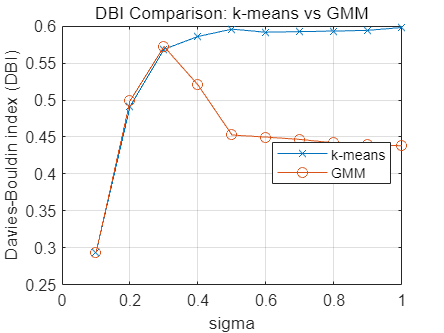

k1=[];
k2=[];
g1=[];
g2=[];

num_clusters = 2;
kmeans_DBI = [];
gmm_DBI = [];
kmeans_si=[];
gmm_si=[];
kmeans_ari = [];
gmm_ari = [];

sigmalist=0.1:0.1:1;
ground_truth = [ones(size(data1og, 1), 1); 2*ones(size(data2og, 1), 1)];

for i=1:length(sigmalist)
    sigma=sigmalist(i);
    data1 = sigma*data1og; 
    mean(data1);
    data2 = sigma*data2og+0.5;
    mean(data2);
    data4=[data1;data2];   
    k = 2;

    % k-means clustering
    kmeans_clusters = kmeans(data4, k);    
    kmeans_DBI_obj = evalclusters(data4, kmeans_clusters, 'DaviesBouldin');
    kmeans_DBI(end+1) = kmeans_DBI_obj.CriterionValues;
    kmeans_silhouette_values = mean(silhouette(data4, kmeans_clusters));
    kmeans_si(end+1) = kmeans_silhouette_values;
    kmeans_ari(end+1) = adjustedRandIndex(kmeans_clusters, ground_truth);

    % GMM clustering
    options = statset('MaxIter', 5000, 'TolFun', 1e-10);
    gmm_model = fitgmdist(data4, k, 'Options', options);
    gmm_model.AIC;
    gmm_clusters = cluster(gmm_model, data4);    
    gmm_DBI_obj = evalclusters(data4, gmm_clusters, 'DaviesBouldin');
    gmm_DBI(end+1) = gmm_DBI_obj.CriterionValues;
    gmm_silhouette_values = mean(silhouette(data4, gmm_clusters));
    gmm_si(end+1) = gmm_silhouette_values;
    gmm_ari(end+1) = adjustedRandIndex(gmm_clusters, ground_truth);
end

figure;
plot(sigmalist, kmeans_DBI, '-x', 'DisplayName', 'k-means');
hold on;
plot(sigmalist, gmm_DBI, '-o', 'DisplayName', 'GMM');
xlabel('sigma');
ylabel('Davies-Bouldin index (DBI)');
title('DBI Comparison: k-means vs GMM');
legend;
hold off;

grid on
legend("Position",[0.61885,0.66898,0.26745,0.12236])

legend(["k-means","GMM"])
legend("Position",[0.61209,0.44943,0.26745,0.12236])

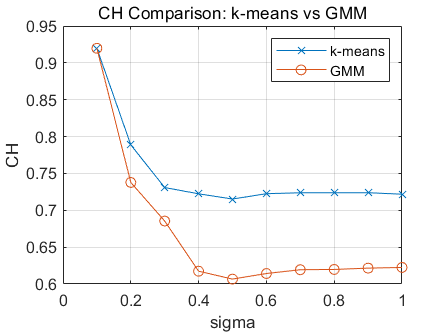


figure;
plot(sigmalist, kmeans_si, '-x', 'DisplayName', 'k-means');
hold on;
plot(sigmalist, gmm_si, '-o', 'DisplayName', 'GMM');
xlabel('sigma');
ylabel('CH');
title('CH Comparison: k-means vs GMM');
legend;
hold off;

grid on

legend(["k-means","GMM"])

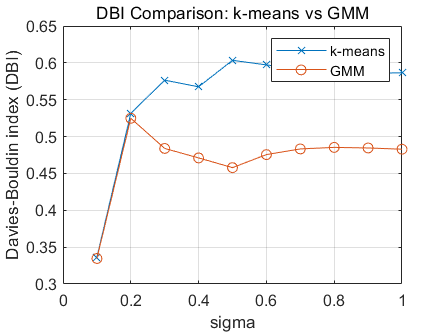

data1og = randn(100,1); 
mean(data1og);
data2og = randn(100,1);
mean(data2og);
data3og=[data1og;data2og];

k1=[];
k2=[];
g1=[];
g2=[];

num_clusters = 2;
kmeans_DBI = [];
gmm_DBI = [];
kmeans_si=[];
gmm_si=[];
kmeans_ari = [];
gmm_ari = [];

sigmalist=0.1:0.1:1;

for i=1:length(sigmalist)
    sigma=sigmalist(i);
    data1 = sigma*data1og; 
    mean(data1);
    data2 = sigma*data2og+0.5;
    mean(data2);
    data4=[data1;data2]; 

    % Generate ground truth based on proximity to 0 or 0.5
    ground_truth = double(abs(data4 - 0.5) < abs(data4));

    k = 2;
    sigma=sigmalist(i);
    data1 = sigma*data1og; 
    mean(data1);
    data2 = sigma*data2og+0.5;
    mean(data2);
    data4=[data1;data2];   
    k = 2;

    % k-means clustering
    kmeans_clusters = kmeans(data4, k);    
    kmeans_DBI_obj = evalclusters(data4, kmeans_clusters, 'DaviesBouldin');
    kmeans_DBI(end+1) = kmeans_DBI_obj.CriterionValues;
    kmeans_silhouette_values = mean(silhouette(data4, kmeans_clusters));
    kmeans_si(end+1) = kmeans_silhouette_values;
    kmeans_ari(end+1) = adjustedRandIndex(kmeans_clusters, ground_truth);

    % GMM clustering
    options = statset('MaxIter', 5000, 'TolFun', 1e-10);
    gmm_model = fitgmdist(data4, k, 'Options', options);
    gmm_model.AIC;
    gmm_clusters = cluster(gmm_model, data4);    
    gmm_DBI_obj = evalclusters(data4, gmm_clusters, 'DaviesBouldin');
    gmm_DBI(end+1) = gmm_DBI_obj.CriterionValues;
    gmm_silhouette_values = mean(silhouette(data4, gmm_clusters));
    gmm_si(end+1) = gmm_silhouette_values;
    gmm_ari(end+1) = adjustedRandIndex(gmm_clusters, ground_truth);
end

% Plotting
figure;
plot(sigmalist, kmeans_DBI, '-x', 'DisplayName', 'k-means');
hold on;
plot(sigmalist, gmm_DBI, '-o', 'DisplayName', 'GMM');
xlabel('sigma');
ylabel('Davies-Bouldin index (DBI)');
title('DBI Comparison: k-means vs GMM');
legend;
hold off;

grid on
legend(["k-means","GMM"])

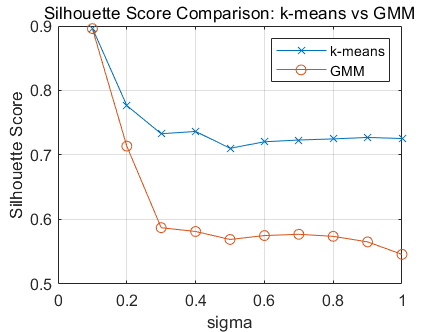


figure;
plot(sigmalist, kmeans_si, '-x', 'DisplayName', 'k-means');
hold on;
plot(sigmalist, gmm_si, '-o', 'DisplayName', 'GMM');
xlabel('sigma');
ylabel('Silhouette Score');
title('Silhouette Score Comparison: k-means vs GMM');
legend;
hold off;

grid on
legend(["k-means","GMM"])

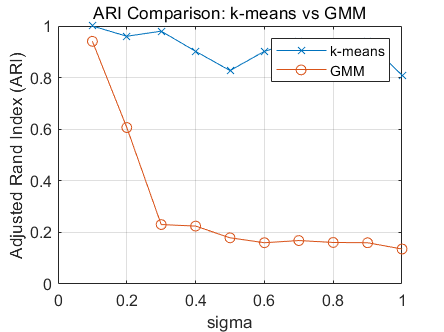


figure;
plot(sigmalist, kmeans_ari, '-x', 'DisplayName', 'k-means');
hold on;
plot(sigmalist, gmm_ari, '-o', 'DisplayName', 'GMM');
xlabel('sigma');
ylabel('Adjusted Rand Index (ARI)');
title('ARI Comparison: k-means vs GMM');
legend;
hold off;

grid on
legend(["k-means","GMM"])

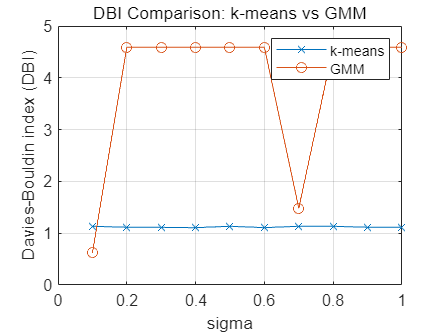

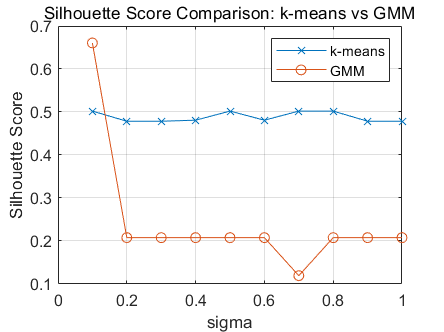

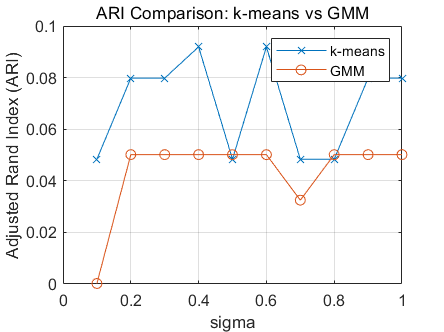

function ari = adjustedRandIndex(labels_true, labels_pred)
    N = length(labels_true);
    [~,~,labels_true] = unique(labels_true);
    [~,~,labels_pred] = unique(labels_pred);
    C = confusionmat(labels_true, labels_pred);
    sum_C = sum(C(:));
    
    sum_comb_C = sum(sum(C, 1) .* (sum(C, 1) - 1) / 2);
    sum_comb_R = sum(sum(C, 2) .* (sum(C, 2) - 1) / 2);
    
    sum_comb = sum(C(:) .* (C(:) - 1) / 2);
    
    expected_index = sum_comb_C * sum_comb_R / (sum_C * (sum_C - 1) / 2);
    max_index = (sum_comb_C + sum_comb_R) / 2;
    
    ari = (sum_comb - expected_index) / (max_index - expected_index);
end
